clear;clc;
% --- paths (use your original logic) ---
if exist('I:\', 'dir')
    input_path = 'I:\My Drive\Data\New Data\EEG epoched\';
    base_output_path = 'C:\Users\sinad\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results';
elseif exist('H:\', 'dir')
    input_path = 'H:\My Drive\Data\New Data\EEG epoched\';
    base_output_path = 'C:\Users\sinad\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results';
elseif exist('G:\', 'dir')
    input_path = 'G:\My Drive\Data\New Data\EEG epoched\';
    base_output_path = 'C:\Users\sdabiri\OneDrive - Georgia Institute of Technology\Dr. Sederberg MaTRIX Lab\temporal_criticality_of_latent_results';
else
    error('Unknown system: Cannot determine input and output paths.');
end
output_path = fullfile(base_output_path, 'longitudinal_dPCA');

if ~exist(output_path, 'dir')
    mkdir(output_path);
    fprintf('Created new output directory: %s\n', output_path);
end

conditions = {'BLA','BLT','P1','P2','P3'}; %,'BLT','P1','P2','P3'
num_ch = 32;
expected_num_time = 1792; % sample count per epoch (your value)
fs = []; % will set from EEG.srate on first load
time_ms_eeg = [];

## 1.1 Load and import file as EEGLAB matrix

data_all_conds = struct();

% Loop through the conditions
for c = 1:length(conditions)
    condition = conditions{c};
    in_dir = fullfile(input_path, condition);
    set_files = dir(fullfile(in_dir, '*.set'));
    names_sorted = sort(cellstr({set_files.name})');
    
    if isempty(names_sorted)
        fprintf('No .set files for %s — skipping\n', condition);
        continue;
    end
    
    % Load excel file paths for P2 and P3 ONCE per condition
    if strcmp(condition, 'P2')
        excel_file_path = fullfile(input_path, 'Indexes for P2.xlsx');
        epoch_trials_p2_500ms = readmatrix(excel_file_path, 'Sheet', 'Audio onset with 500 ms tactile');
        epoch_trials_p2_2000ms = readmatrix(excel_file_path, 'Sheet', 'Audio onset with 2000 ms tactil');
    elseif strcmp(condition, 'P3')
        excel_file_path = fullfile(input_path, 'Indexes for P3.xlsx');
        epoch_trials_p3_500ms = readmatrix(excel_file_path, 'Sheet', 'Audio onset with 500 ms tactile');
        epoch_trials_p3_missing = readmatrix(excel_file_path, 'Sheet', 'Audio onset with missing tactil');
    end

    % --- NEW: Loop through ALL subjects for this condition ---
    for s = 1:length(names_sorted)
        file_to_load = names_sorted{s}; 
        fprintf('Loading Subj %d/%d (%s) for condition: %s\n', s, length(names_sorted), file_to_load, condition);
        
        EEG = pop_loadset('filename', file_to_load, 'filepath', in_dir);
        if isempty(fs), fs = EEG.srate; end
        
        if isempty(time_ms_eeg)
            time_ms_eeg = linspace(0, 3.5 , size(EEG.data, 2)); 
        end
        
        % Extract data and store in a cell array to avoid dimension mismatch
        if ismember(condition, {'BLA', 'BLT', 'P1'})
            epoch_trials = 1:2:EEG.trials;
            data_all_conds.(condition){s} = EEG.data(:, :, epoch_trials);
            
        elseif strcmp(condition, 'P2')
            epoch_trials_p2 = 1:2:EEG.trials;     
            data_all_conds.(condition){s} = EEG.data(:, :, epoch_trials_p2);
            data_all_conds.P2_500{s}      = EEG.data(:, :, epoch_trials_p2_500ms);
            data_all_conds.P2_2000{s}     = EEG.data(:, :, epoch_trials_p2_2000ms);
            
        elseif strcmp(condition, 'P3')
            epoch_trials_p3 = 1:2:EEG.trials;
            data_all_conds.(condition){s}   = EEG.data(:, :, epoch_trials_p3);
            data_all_conds.P3_500{s}        = EEG.data(:, :, epoch_trials_p3_500ms);
            data_all_conds.P3_missing{s}    = EEG.data(:, :, epoch_trials_p3_missing);
        end
    end
end

Loading Subj 1/14 (binepochs filtered ICArej BLAAvgBOS10.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS10.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS10.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 2/14 (binepochs filtered ICArej BLAAvgBOS11.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS11.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS11.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 3/14 (binepochs filtered ICArej BLAAvgBOS12.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS12.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS12.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 4/14 (binepochs filtered ICArej BLAAvgBOS13.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS13.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS13.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 5/14 (binepochs filtered ICArej BLAAvgBOS15.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS15.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS15.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 6/14 (binepochs filtered ICArej BLAAvgBOS16.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS16.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS16.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 7/14 (binepochs filtered ICArej BLAAvgBOS17.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS17.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS17.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 8/14 (binepochs filtered ICArej BLAAvgBOS2.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS2.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS2.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 9/14 (binepochs filtered ICArej BLAAvgBOS3.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS3.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS3.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 10/14 (binepochs filtered ICArej BLAAvgBOS5.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS5.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS5.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 11/14 (binepochs filtered ICArej BLAAvgBOS6.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS6.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS6.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 12/14 (binepochs filtered ICArej BLAAvgBOS7.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS7.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS7.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 13/14 (binepochs filtered ICArej BLAAvgBOS8.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS8.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS8.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 14/14 (binepochs filtered ICArej BLAAvgBOS9.set) for condition: BLA


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS9.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLA\binepochs filtered ICArej BLAAvgBOS9.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 1/14 (binepochs filtered ICArej BLTAvgBOS10.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS10.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS10.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 2/14 (binepochs filtered ICArej BLTAvgBOS11.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS11.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS11.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 3/14 (binepochs filtered ICArej BLTAvgBOS12.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS12.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS12.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 4/14 (binepochs filtered ICArej BLTAvgBOS13.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS13.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS13.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 5/14 (binepochs filtered ICArej BLTAvgBOS15.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS15.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS15.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 6/14 (binepochs filtered ICArej BLTAvgBOS16.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS16.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS16.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 7/14 (binepochs filtered ICArej BLTAvgBOS17.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS17.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS17.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 8/14 (binepochs filtered ICArej BLTAvgBOS2.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS2.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS2.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 9/14 (binepochs filtered ICArej BLTAvgBOS3.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS3.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS3.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 10/14 (binepochs filtered ICArej BLTAvgBOS5.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS5.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS5.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 11/14 (binepochs filtered ICArej BLTAvgBOS6.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS6.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS6.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 12/14 (binepochs filtered ICArej BLTAvgBOS7.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS7.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS7.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 13/14 (binepochs filtered ICArej BLTAvgBOS8.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS8.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS8.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 14/14 (binepochs filtered ICArej BLTAvgBOS9.set) for condition: BLT


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS9.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\BLT\binepochs filtered ICArej BLTAvgBOS9.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 1/14 (binepochs filtered ICArej P1AvgBOS10.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS10.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS10.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 2/14 (binepochs filtered ICArej P1AvgBOS11.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS11.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS11.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 3/14 (binepochs filtered ICArej P1AvgBOS12.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS12.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS12.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 4/14 (binepochs filtered ICArej P1AvgBOS13.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS13.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS13.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 5/14 (binepochs filtered ICArej P1AvgBOS15.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS15.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS15.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 6/14 (binepochs filtered ICArej P1AvgBOS16.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS16.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS16.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 7/14 (binepochs filtered ICArej P1AvgBOS17.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS17.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS17.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 8/14 (binepochs filtered ICArej P1AvgBOS2.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS2.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS2.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 9/14 (binepochs filtered ICArej P1AvgBOS3.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS3.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS3.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 10/14 (binepochs filtered ICArej P1AvgBOS5.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS5.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS5.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 11/14 (binepochs filtered ICArej P1AvgBOS6.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS6.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS6.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 12/14 (binepochs filtered ICArej P1AvgBOS7.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS7.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS7.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 13/14 (binepochs filtered ICArej P1AvgBOS8.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS8.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS8.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 14/14 (binepochs filtered ICArej P1AvgBOS9.set) for condition: P1


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS9.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P1\binepochs filtered ICArej P1AvgBOS9.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 1/14 (binepochs filtered ICArej P2AvgBOS10.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS10.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS10.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 2/14 (binepochs filtered ICArej P2AvgBOS11.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS11.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS11.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 3/14 (binepochs filtered ICArej P2AvgBOS12.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS12.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS12.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 4/14 (binepochs filtered ICArej P2AvgBOS13.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS13.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS13.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 5/14 (binepochs filtered ICArej P2AvgBOS15.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS15.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS15.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 6/14 (binepochs filtered ICArej P2AvgBOS16.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS16.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS16.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 7/14 (binepochs filtered ICArej P2AvgBOS17.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS17.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS17.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 8/14 (binepochs filtered ICArej P2AvgBOS2.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS2.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS2.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 9/14 (binepochs filtered ICArej P2AvgBOS3.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS3.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS3.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 10/14 (binepochs filtered ICArej P2AvgBOS5.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS5.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS5.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 11/14 (binepochs filtered ICArej P2AvgBOS6.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS6.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS6.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 12/14 (binepochs filtered ICArej P2AvgBOS7.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS7.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS7.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 13/14 (binepochs filtered ICArej P2AvgBOS8.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS8.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS8.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 14/14 (binepochs filtered ICArej P2AvgBOS9.set) for condition: P2


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS9.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P2\binepochs filtered ICArej P2AvgBOS9.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 1/14 (binepochs filtered ICArej P3AvgBOS10.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS10.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS10.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 2/14 (binepochs filtered ICArej P3AvgBOS11.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS11.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS11.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 3/14 (binepochs filtered ICArej P3AvgBOS12.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS12.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS12.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 4/14 (binepochs filtered ICArej P3AvgBOS13.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS13.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS13.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 5/14 (binepochs filtered ICArej P3AvgBOS15.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS15.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS15.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 6/14 (binepochs filtered ICArej P3AvgBOS16.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS16.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS16.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 7/14 (binepochs filtered ICArej P3AvgBOS17.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS17.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS17.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 8/14 (binepochs filtered ICArej P3AvgBOS2.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS2.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS2.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 9/14 (binepochs filtered ICArej P3AvgBOS3.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS3.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS3.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 10/14 (binepochs filtered ICArej P3AvgBOS5.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS5.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS5.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 11/14 (binepochs filtered ICArej P3AvgBOS6.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS6.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS6.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 12/14 (binepochs filtered ICArej P3AvgBOS7.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS7.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS7.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 13/14 (binepochs filtered ICArej P3AvgBOS8.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS8.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS8.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


Loading Subj 14/14 (binepochs filtered ICArej P3AvgBOS9.set) for condition: P3


pop_loadset(): loading file G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS9.set ...


Reading float file 'G:\My Drive\Data\New Data\EEG epoched\P3\binepochs filtered ICArej P3AvgBOS9.fdt'...
eeg_checkset: recomputing the ICA activation matrix ...


## 1.2 Visualizing the conditions raw data

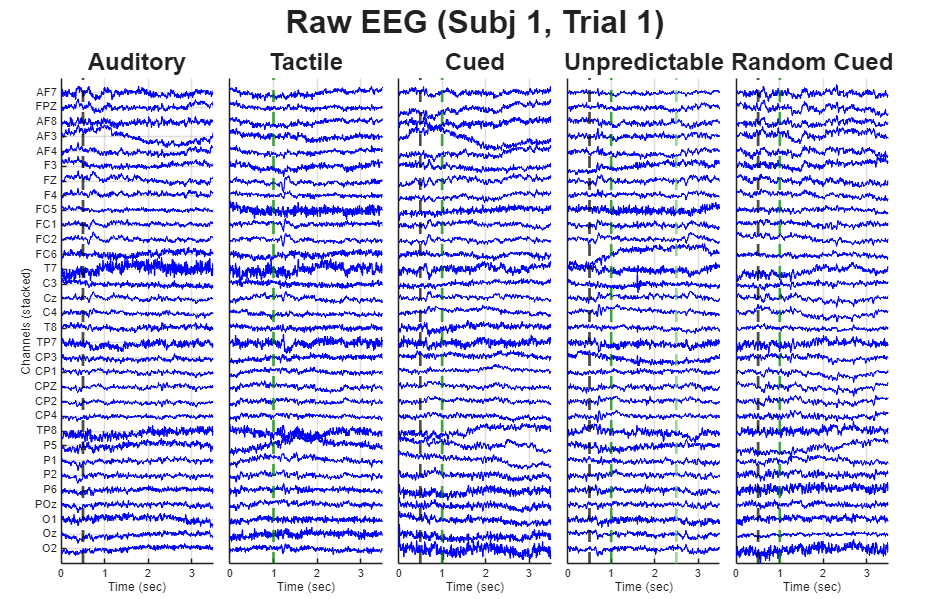

%% Visualizing Specific Trial for a Specific Subject
target_trial = 1; 
target_subject = 1; 

if exist('EEG', 'var') && isfield(EEG, 'chanlocs')
    display_channels_str = {EEG.chanlocs.labels};
else
    display_channels_str = cellstr(num2str((1:size(data_all_conds.BLT{1}, 1))')); 
end

num_channels_plot = length(display_channels_str);
plot_conds = fieldnames(data_all_conds);
num_conds = length(conditions); % Just plotting the base conditions for now

figure('Position',[50 50 2200 1400])
t = tiledlayout(1, num_conds, 'TileSpacing', 'compact', 'Padding', 'compact');
title(t, sprintf('Raw EEG (Subj %d, Trial %d)', target_subject, target_trial), 'FontSize', 24, 'FontWeight', 'bold');

offset = 30; 
tick_positions = (num_channels_plot - (1:num_channels_plot)) * offset;

for c = 1:num_conds
    cond_name = conditions{c};
    
    % Access the cell for the subject, then slice the 3rd dimension for the trial
    data_to_plot = data_all_conds.(cond_name){target_subject}(:, :, target_trial);
    
    nexttile;
    hold on
    for ch = 1:num_channels_plot
        plot(time_ms_eeg, data_to_plot(ch, :) + (num_channels_plot - ch)*offset, 'b', 'LineWidth', 1.0);
    end
    
    if strcmp(cond_name, 'BLT')
        xline(1.0, '--', 'Color', [0 0.5 0], 'LineWidth', 2);
    elseif any(strcmp(cond_name, {'P1','P3'}))
        xline(0.5, 'k--', 'LineWidth', 2);
        xline(1.0, '--', 'Color', [0 0.5 0], 'LineWidth', 2);
    elseif strcmp(cond_name, 'P2')
        xline(0.5, 'k--', 'LineWidth', 2);
        xline(1.0, '--', 'Color', [0 0.5 0], 'LineWidth', 2);
        xline(2.5, '--', 'Color', [0.4 0.8 0.4], 'LineWidth', 2);
    else
        xline(0.5, 'k--', 'LineWidth', 2);
    end
    
    hold off
    xlim([min(time_ms_eeg), max(time_ms_eeg)]); 
    ylim([-offset, num_channels_plot*offset]);
    xlabel('Time (sec)'); 
    
    if c == 1
        ylabel('Channels (stacked)');
        yticks(flip(tick_positions));
        yticklabels(flip(string(display_channels_str)));
    else
        yticks([]);
    end
    if ismember(cond_name, 'BLA')
        plot_name = 'Auditory';
    elseif ismember(cond_name, 'BLT')
        plot_name = 'Tactile';    
    elseif ismember(cond_name, 'P1')
        plot_name = 'Cued';
    elseif ismember(cond_name, 'P2')
        plot_name = 'Unpredictable';
    elseif ismember(cond_name, 'P3')
        plot_name = 'Random Cued';
    end
    title(plot_name, 'FontSize', 18);
    grid on;
end

disp('Calculating averages across trials and subjects...');

Calculating averages across trials and subjects...



cond_names = fieldnames(data_all_conds);
data_subj_avg = struct();
data_grand_avg = struct();
data_grand_std = struct();

for i = 1:length(cond_names)
    c_name = cond_names{i};
    num_subjects = length(data_all_conds.(c_name));
    
    % 1. Average across trials for EACH subject
    % Preallocate [Channels x Time x Subjects]
    subj_avg_matrix = zeros(num_ch, length(time_ms_eeg), num_subjects);
    
    for s = 1:num_subjects
        % Average across dim 3 (trials)
        subj_avg_matrix(:,:,s) = mean(data_all_conds.(c_name){s}, 3, 'omitnan');
    end
    data_subj_avg.(c_name) = subj_avg_matrix;
    
    % 2. Average across subjects (Grand Average)
    data_grand_avg.(c_name) = mean(subj_avg_matrix, 3, 'omitnan');
    
    % 3. Standard Deviation across subjects (for shaded error bars)
    data_grand_std.(c_name) = std(subj_avg_matrix, 0, 3, 'omitnan');
end

%% Visualizing Grand Average with STD Shading
channels_to_plot = {'AF3', 'F3', 'FZ', 'FC5', 'FC1',  'T7', 'C3', 'Cz', 'C4', 'T8', 'TP7', 'CP3', 'CP1',  'P5', 'P1', 'O1', 'Oz', 'O2'};

[~, chan_idx] = ismember(channels_to_plot, display_channels_str);
valid_mask = chan_idx > 0;
chan_idx = chan_idx(valid_mask);
display_channels_str = channels_to_plot(valid_mask);

num_channels_plot = length(display_channels_str);
num_conds = length(conditions); 


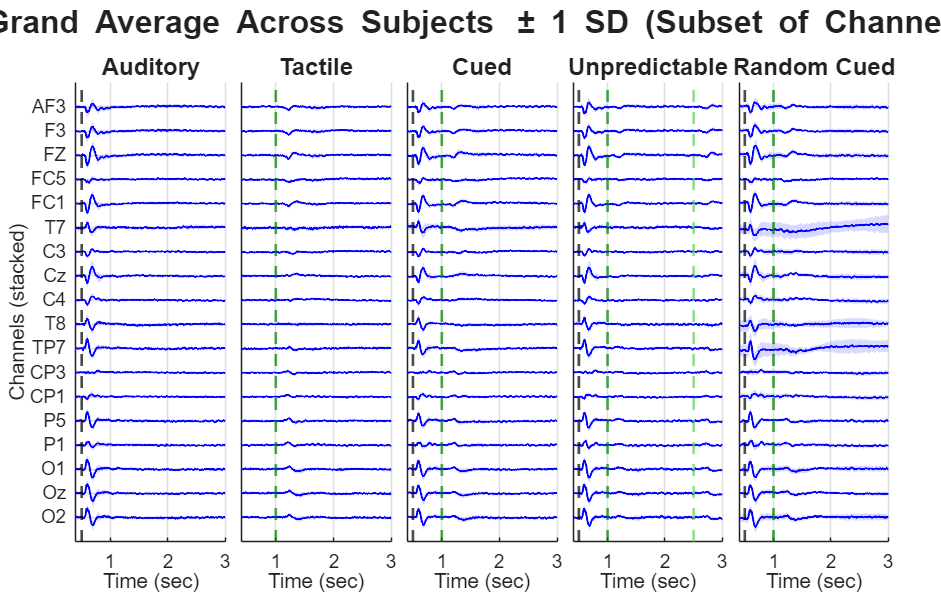

figure('Position',[50 50 2200 1400])
t = tiledlayout(1, num_conds, 'TileSpacing', 'compact', 'Padding', 'compact');
title(t, 'Grand Average Across Subjects \pm 1 SD (Subset of Channels)', 'FontSize', 22, 'FontWeight', 'bold');

offset = 15; 
tick_positions = (num_channels_plot - (1:num_channels_plot)) * offset;
time_fill = [time_ms_eeg, fliplr(time_ms_eeg)]; % X-axis for shading

for c = 1:num_conds
    cond_name = conditions{c};
    
    nexttile;
    hold on
    
    for ch = 1:num_channels_plot
        actual_ch = chan_idx(ch);
        y_shift = (num_channels_plot - ch) * offset;
        
        % Extract mean and std for this specific channel
        mu = data_grand_avg.(cond_name)(actual_ch, :) + y_shift;
        sigma = data_grand_std.(cond_name)(actual_ch, :);
        
        % Create boundaries for the shaded standard deviation
        y_bound = [mu + sigma, fliplr(mu - sigma)];
        
        % Plot Shaded STD Area first (so it sits behind the line)
        fill(time_fill, y_bound, 'b', 'FaceAlpha', 0.15, 'EdgeColor', 'none', 'HandleVisibility', 'off');
        
        % Plot Mean Line
        plot(time_ms_eeg, mu, 'b', 'LineWidth', 1.5);
    end
    
    % Add Vertical Event Lines
    if strcmp(cond_name, 'BLT')
        xline(1.0, '--', 'Color', [0 0.5 0], 'LineWidth', 2);
    elseif any(strcmp(cond_name, {'P1','P3'}))
        xline(0.5, 'k--', 'LineWidth', 2);
        xline(1.0, '--', 'Color', [0 0.5 0], 'LineWidth', 2);
    elseif strcmp(cond_name, 'P2')
        xline(0.5, 'k--', 'LineWidth', 2);
        xline(1.0, '--', 'Color', [0 0.5 0], 'LineWidth', 2);
        xline(2.5, '--', 'Color', [0.4 0.8 0.4], 'LineWidth', 2);
    else
        xline(0.5, 'k--', 'LineWidth', 2);
    end
    
    hold off
    xlim([0.4, 3]); 
    ylim([-offset, num_channels_plot*offset]);
    xlabel('Time (sec)'); 
    
    if c == 1
        ylabel('Channels (stacked)');
        yticks(flip(tick_positions));
        yticklabels(flip(string(display_channels_str)));
    else
        yticks([]); 
    end
    
    set(gca,'FontSize',14);
    if ismember(cond_name, 'BLA')
        plot_name = 'Auditory';
    elseif ismember(cond_name, 'BLT')
        plot_name = 'Tactile';    
    elseif ismember(cond_name, 'P1')
        plot_name = 'Cued';
    elseif ismember(cond_name, 'P2')
        plot_name = 'Unpredictable';
    elseif ismember(cond_name, 'P3')
        plot_name = 'Random Cued';
    end
    title(plot_name, 'FontSize', 18);
    grid on;
end

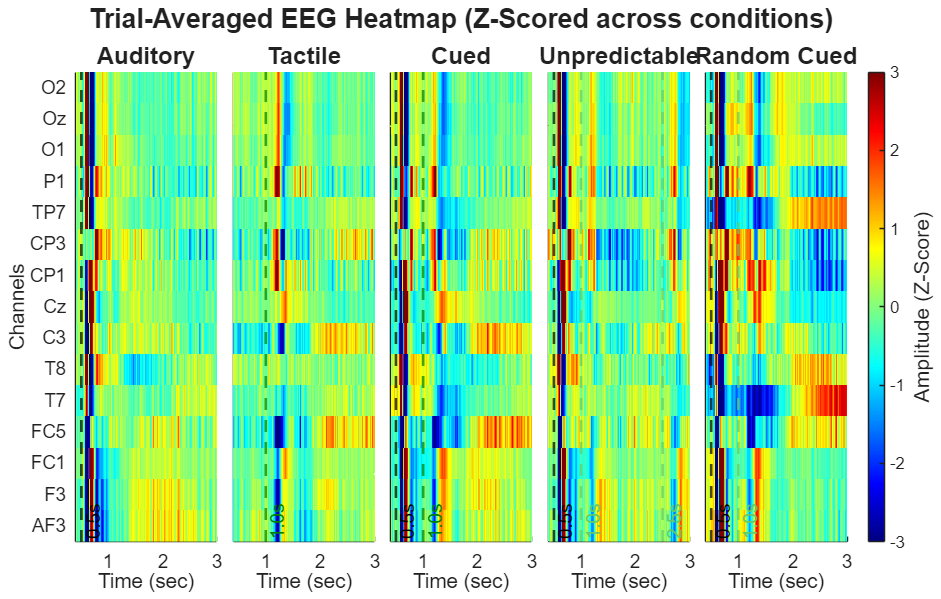

% 1. Define the specific channels you want to plot
channels_to_plot = {'AF3', 'F3', 'Fz', 'FC1', 'FC5', 'T7', 'T8', 'C3', 'Cz', 'CP1', 'CP3', 'TP7', 'P1', 'O1', 'Oz', 'O2'};

% Safely extract all 32 channel labels 
if exist('EEG', 'var') && isfield(EEG, 'chanlocs')
    all_channels_str = {EEG.chanlocs.labels};
else
    % Fallback if EEG structure isn't in the workspace
    all_channels_str = cellstr(num2str((1:size(data_grand_avg.BLT, 1))')); 
end

% 2. Find the indices of the requested channels within the full list
[~, chan_idx] = ismember(channels_to_plot, all_channels_str);

% Safety check: remove any channels from the list that weren't found
valid_mask = chan_idx > 0;
chan_idx = chan_idx(valid_mask);
display_channels_str = channels_to_plot(valid_mask);

num_channels_plot = length(display_channels_str);

% Define your observed conditions (ensure 'BLA' is included if you use it in the loop)
conditions = {'BLA', 'BLT', 'P1', 'P2', 'P3'};
num_conds = length(conditions); 

% --- NEW: Z-score across all conditions per channel ---
% Concatenate all condition data to compute global mean and std per channel
concat_data = [];
for c = 1:num_conds
    cond_name = conditions{c};
    concat_data = [concat_data, data_grand_avg.(cond_name)];
end

% Calculate mean and std specifically for the selected channels
mu_chan = mean(concat_data(chan_idx, :), 2);
sigma_chan = std(concat_data(chan_idx, :), 0, 2);

% Prevent division by zero if a channel is completely flat
sigma_chan(sigma_chan == 0) = 1; 

% Set color limits to typical Z-score bounds (±3 standard deviations)
color_limits = [-3, 3]; 

% Widen the figure to comfortably fit side-by-side plots
figure('Position',[50 50 2200 1400])
t = tiledlayout(1, num_conds, 'TileSpacing', 'compact', 'Padding', 'compact');
title(t, 'Trial-Averaged EEG Heatmap (Z-Scored across conditions)', 'FontSize', 20, 'FontWeight', 'bold');

% Custom colors for the event lines
dark_green  = [0 0.5 0];
light_green = [0.4 0.8 0.4];

% Loop through all conditions to generate the tiles dynamically
for c = 1:num_conds
    cond_name = conditions{c};
    
    % --- Extract and Z-score the Data ---
    raw_data = data_grand_avg.(cond_name)(chan_idx, :);
    data_to_plot = (raw_data - mu_chan) ./ sigma_chan; % Z-score calculation
    
    nexttile;
    hold on;
    
    % 1. Plot the Heatmap
    imagesc(time_ms_eeg, 1:num_channels_plot, data_to_plot);
    
    % Apply the z-score color limits
    clim(color_limits); 
    
    % 2. Add Vertical Event Lines
    if strcmp(cond_name, 'BLT')
        xline(1.0, '--', '1.0s', 'Color', dark_green, 'LineWidth', 2, 'FontSize', 14, 'LabelVerticalAlignment', 'bottom');
    else
        xline(0.5, 'k--', '0.5s', 'LineWidth', 2, 'FontSize', 14, 'LabelVerticalAlignment', 'bottom');
    end
    
    if ismember(cond_name, 'P1')
        xline(1.0, '--', '1.0s', 'Color', dark_green, 'LineWidth', 2, 'FontSize', 14, 'LabelVerticalAlignment', 'bottom');
    elseif strcmp(cond_name, 'P2')
        xline(1.0, '--', '1.0s', 'Color', light_green, 'LineWidth', 2, 'FontSize', 14, 'LabelVerticalAlignment', 'bottom');
        xline(2.5, '--', '2.5s', 'Color', light_green, 'LineWidth', 2, 'FontSize', 14, 'LabelVerticalAlignment', 'bottom');
    elseif strcmp(cond_name, 'P3')
        xline(1.0, '--', '1.0s', 'Color', light_green, 'LineWidth', 2, 'FontSize', 14, 'LabelVerticalAlignment', 'bottom');
    end
    
    hold off;
    
    % Fit axes
    xlim([0.4, 3]); 
    ylim([0.5, num_channels_plot + 0.5]); 
    xlabel('Time (sec)'); 
    
    % Y-Axis formatting
    if c == 1
        ylabel('Channels');
        yticks(1:num_channels_plot);
        yticklabels(display_channels_str);
    else
        yticks([]); 
    end
    
    set(gca, 'YDir', 'normal', 'FontSize', 14);
    
    % Custom Titles
    if ismember(cond_name, 'BLA')
        plot_name = 'Auditory';
    elseif ismember(cond_name, 'BLT')
        plot_name = 'Tactile';    
    elseif ismember(cond_name, 'P1')
        plot_name = 'Cued';
    elseif ismember(cond_name, 'P2')
        plot_name = 'Unpredictable';
    elseif ismember(cond_name, 'P3')
        plot_name = 'Random Cued';
    else
        plot_name = cond_name;
    end
    title(sprintf('%s', plot_name), 'FontSize', 18);
    
end

% Use a divergent colormap suitable for Z-scores
colormap('jet'); 
cb = colorbar;
cb.Layout.Tile = 'east'; 
cb.Label.String = 'Amplitude (Z-Score)';
cb.Label.FontSize = 16;

## 2.0 Sliding Window PCA (120 msec) with Vector Alignment

disp('Performing Sliding Window PCA with Cross-Window Cosine Similarity Alignment...');

Performing Sliding Window PCA with Cross-Window Cosine Similarity Alignment...



pca_conditions = {'BLA', 'BLT', 'P1'};
num_comps = 4; 

% Turn off the annoying PCA rank deficiency warning
warning('off', 'stats:pca:ColRankDefX'); 

% 1. Define Sliding Window Parameters
win_ms = 120; 
step_ms = 20; 

% Convert ms to samples
if isempty(fs), fs = 512; end 
win_samples = round((win_ms / 1000) * fs);
step_samples = round((step_ms / 1000) * fs);

total_samples = length(time_ms_eeg);
win_starts = 1:step_samples:(total_samples - win_samples + 1);
n_windows = length(win_starts);

% Calculate the center time of each window for plotting
time_windows = zeros(1, n_windows);

% Pre-allocate storage
pca_dynamic = struct();

for i = 1:length(pca_conditions)
    c_name = pca_conditions{i};
    X = data_grand_avg.(c_name); % Size: [num_ch x time]
    
    % Pre-allocate matrices to hold data across time windows
    coeffs_time = zeros(num_ch, num_comps, n_windows);
    exp_var_time = zeros(num_comps, n_windows);
    mu_time = zeros(num_ch, n_windows);
    comp_time_matrix = zeros(num_comps, n_windows);
    
    % --- NEW: Pre-allocate Tracking Structure ---
    % Creates a 1x4 structure array (one for each PC)
    tracking_struct = struct('matched_pc', cell(1, num_comps), 'similarity', cell(1, num_comps));
    for pc = 1:num_comps
        tracking_struct(pc).matched_pc = zeros(1, n_windows);
        tracking_struct(pc).similarity = zeros(1, n_windows);
    end
    
    prev_coeff = []; % Used to track and align
    
    for w = 1:n_windows
        % Define the exact sample range for this window
        idx = win_starts(w):(win_starts(w) + win_samples - 1);
        time_windows(w) = mean(time_ms_eeg(idx)); % Center of the window
        
        X_win = X(:, idx);
        
        % Perform PCA strictly on this chunk
        [coeff, score, ~, ~, exp_var, mu] = pca(X_win');
        
        % Keep only top components
        coeff = coeff(:, 1:min(num_comps, size(coeff,2)));
        score = score(:, 1:min(num_comps, size(score,2))); 
        exp_var = exp_var(1:min(num_comps, length(exp_var)));
        
        % --- ALIGNMENT STEP (Cosine Similarity Matching) ---
        if w > 1
            sim_matrix = prev_coeff' * coeff; 
            
            new_coeff = zeros(size(coeff));
            new_score = zeros(size(score));
            new_exp_var = zeros(size(exp_var));
            
            available_curr_pcs = 1:size(coeff, 2); 
            
            for pc_prev = 1:size(prev_coeff, 2)
                % Find the current PC with highest absolute cosine similarity
                [~, best_idx] = max(abs(sim_matrix(pc_prev, available_curr_pcs)));
                best_curr_pc = available_curr_pcs(best_idx);
                
                % Extract the raw cosine similarity value
                actual_sim = sim_matrix(pc_prev, best_curr_pc);
                
                % --- NEW: Store tracking data in the Structure ---
                tracking_struct(pc_prev).matched_pc(w) = best_curr_pc;
                tracking_struct(pc_prev).similarity(w) = actual_sim;
                
                % Map to the new slot and correct the sign if necessary
                if actual_sim < 0
                    new_coeff(:, pc_prev) = -coeff(:, best_curr_pc);
                    new_score(:, pc_prev) = -score(:, best_curr_pc);
                else
                    new_coeff(:, pc_prev) = coeff(:, best_curr_pc);
                    new_score(:, pc_prev) = score(:, best_curr_pc);
                end
                
                new_exp_var(pc_prev) = exp_var(best_curr_pc);
                available_curr_pcs(best_idx) = [];
            end
            
            coeff = new_coeff;
            score = new_score;
            exp_var = new_exp_var;
            
        else
            % Very first window: PCs match themselves perfectly
            for pc = 1:size(coeff, 2)
                tracking_struct(pc).matched_pc(w) = pc;
                tracking_struct(pc).similarity(w) = 1.0;
            end
        end
        
        % Store data
        prev_coeff = coeff;
        coeffs_time(:, 1:size(coeff,2), w) = coeff;
        exp_var_time(1:length(exp_var), w) = exp_var;
        mu_time(:, w) = mu';
        
        comp_time_matrix(1:size(score,2), w) = mean(score, 1)';
    end
    
    % Save everything to the dynamic structure
    pca_dynamic.(c_name).coeffs = coeffs_time;        
    pca_dynamic.(c_name).exp_var = exp_var_time;      
    pca_dynamic.(c_name).mu = mu_time;                
    pca_dynamic.(c_name).comp_time = comp_time_matrix; 
    
    % --- NEW: Attach the structured tracking data ---
    pca_dynamic.(c_name).cos_sim_tracking = tracking_struct;
end

## 2.1 Plot Explained Variance Across Sliding Windows

disp('Plotting Cumulative Explained Variance...');

Plotting Cumulative Explained Variance...


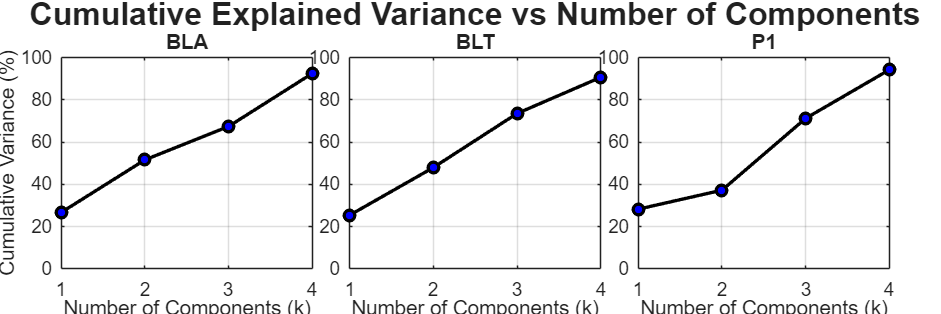


figure('Position', [50 50 1200 400], 'Name', 'Cumulative Variance');
t = tiledlayout(1, 3, 'TileSpacing', 'compact', 'Padding', 'compact');
title(t, 'Cumulative Explained Variance vs Number of Components', 'FontSize', 24, 'FontWeight', 'bold');

for i = 1:length(pca_conditions)
    c_name = pca_conditions{i};
    nexttile;
    
    % Average the explained variance across all sliding windows (Dim 2)
    mean_exp_var = mean(pca_dynamic.(c_name).exp_var, 2);
    
    % Calculate cumulative sum to get the total variance explained up to k
    cum_var = cumsum(mean_exp_var);
    
    % Plot the Pareto/Scree curve
    plot(1:num_comps, cum_var, '-ok', 'LineWidth', 2.5, 'MarkerFaceColor', 'b', 'MarkerSize', 8);
    
    xlim([1 num_comps]);
    ylim([0 100]); % Assuming explained variance is a percentage 0-100
    xticks(1:num_comps);
    
    xlabel('Number of Components (k)');
    if i == 1
        ylabel('Cumulative Variance (%)'); 
    end
    title(c_name, 'FontSize', 18);
    grid on; 
    set(gca,'FontSize',14);
end

## 2.3 Visualizing Dynamic Topoplots & Time Courses (Grid)

disp('Plotting Dynamic Topoplots and Time Courses across Sliding Windows...');

Plotting Dynamic Topoplots and Time Courses across Sliding Windows...


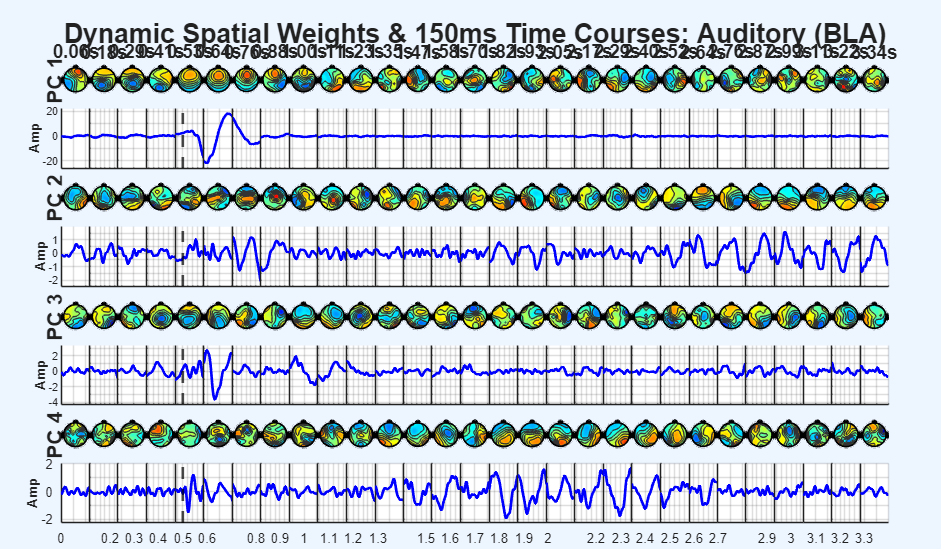

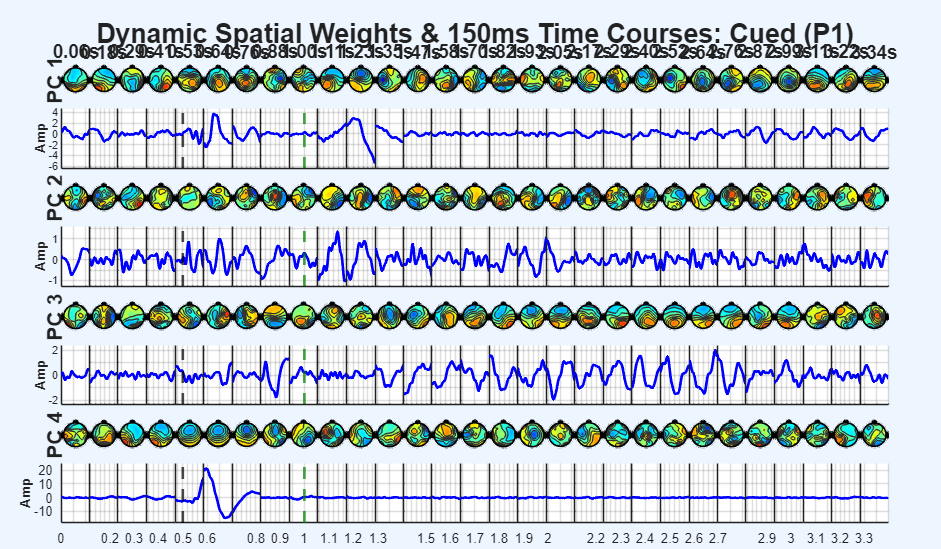


% Suppress layout warnings
warning('off', 'all');

num_comps_plot = 4;
dark_green  = [0 0.5 0];

% --- VISUAL CLARITY SETTING ---
% Plotting 66 windows * 4 PCs * 2 (topo + trace) = 528 subplots!
% 'plot_step = 2' skips every other window (effectively plotting every 100ms instead of 50ms) to keep it readable.
plot_step = win_ms/step_ms; 
plot_win_idx = 1:plot_step:n_windows;
num_plot_windows = length(plot_win_idx);

for i = 1:length(pca_conditions)
    c_name = pca_conditions{i};
    
    % Create a very tall and wide figure for the grid
    figure('Position', [50, 50, 2400, 1400], 'Name', sprintf('Dynamic PCA: %s', c_name));
    
    % Layout: Rows = PCs * 2 (Topo + Trace), Columns = Time Windows
    t = tiledlayout(num_comps_plot * 2, num_plot_windows, 'TileSpacing', 'none', 'Padding', 'compact');
    
    % Dynamic Title
    if strcmp(c_name, 'BLA'), clean_name = 'Auditory (BLA)';
    elseif strcmp(c_name, 'BLT'), clean_name = 'Tactile (BLT)';
    elseif strcmp(c_name, 'P1'), clean_name = 'Cued (P1)';
    else, clean_name = c_name; end
    
    title(t, sprintf('Dynamic Spatial Weights & 150ms Time Courses: %s', clean_name), 'FontSize', 16, 'FontWeight', 'bold');
    
    % --- CRITICAL: GLOBAL LIMITS ---
    % 1. Global Color Scale for Topoplots
    max_topo = max(abs(pca_dynamic.(c_name).coeffs(:)));
    clim_bound = [-max_topo, max_topo] * 0.8; % Saturate top 20%
    
    % 2. Global Y-Limits for Traces (so waves don't artificially stretch in quiet windows)
    trace_limits = zeros(num_comps_plot, 2);
    for pc = 1:num_comps_plot
        min_val = inf; max_val = -inf;
        for col = 1:num_plot_windows
             w = plot_win_idx(col);
             idx = win_starts(w):(win_starts(w) + win_samples - 1);
             X_win = data_grand_avg.(c_name)(:, idx);
             trace = (X_win' - pca_dynamic.(c_name).mu(:, w)') * pca_dynamic.(c_name).coeffs(:, pc, w);
             min_val = min(min_val, min(trace));
             max_val = max(max_val, max(trace));
        end
        pad = (max_val - min_val) * 0.1;
        if pad == 0, pad = 1; end
        trace_limits(pc, :) = [min_val - pad, max_val + pad];
    end
    
    % Generate the Grid
    for pc = 1:num_comps_plot
        for col = 1:num_plot_windows
            w = plot_win_idx(col); % The actual window index
            idx = win_starts(w):(win_starts(w) + win_samples - 1);
            time_win = time_ms_eeg(idx); % Exact time vector for this 150ms window
            
            % ==========================================
            % 1. PLOT THE TOPOPLOT (Odd Rows)
            % ==========================================
            topo_tile_idx = (pc - 1) * 2 * num_plot_windows + col;
            nexttile(topo_tile_idx);
            
            spatial_weights = pca_dynamic.(c_name).coeffs(:, pc, w);
            topoplot(spatial_weights, EEG.chanlocs, 'electrodes', 'off', 'maplimits', clim_bound);
            
            % Add Time titles to the very top row
            if pc == 1
                title(sprintf('%.2fs', time_windows(w)), 'FontSize', 14, 'FontWeight', 'bold');
            end
            
            % Add PC labels to the very leftmost column
            if col == 1
                text(-0.8, 0, sprintf('PC %d', pc), 'FontSize', 16, 'FontWeight', 'bold', ...
                    'Rotation', 90, 'HorizontalAlignment', 'center');
            end
            
            % ==========================================
            % 2. PLOT THE TIME COURSE (Even Rows)
            % ==========================================
            trace_tile_idx = ((pc - 1) * 2 + 1) * num_plot_windows + col;
            nexttile(trace_tile_idx);
            hold on;
            
            % Dynamically project this window's data onto this window's PC weights
            X_win = data_grand_avg.(c_name)(:, idx);
            trace = (X_win' - pca_dynamic.(c_name).mu(:, w)') * pca_dynamic.(c_name).coeffs(:, pc, w);
            
            plot(time_win, trace, 'b', 'LineWidth', 2);
            
            % --- Overlay Vertical Event Lines ---
            % Auditory Cue at 0.5s
            if 0.5 >= time_win(1) && 0.5 <= time_win(end)
                xline(0.5, 'k--', 'LineWidth', 2);
            end
            % Tactile Stimulus at 1.0s (for BLT and P1)
            if ismember(c_name, {'BLT', 'P1'}) && 1.0 >= time_win(1) && 1.0 <= time_win(end)
                xline(1.0, '--', 'Color', dark_green, 'LineWidth', 2);
            end
            
            hold off;
            
            % Formatting
            xlim([time_win(1), time_win(end)]);
            ylim(trace_limits(pc, :));
            grid on;
            
            % Hide X-ticks unless it's the very bottom row
            if pc < num_comps_plot
                xticklabels({});
            else
                % Keep X-ticks but rotate them slightly if they overlap
                set(gca, 'FontSize', 10);
            end
            
            % Hide Y-ticks unless it's the very first column
            if col > 1
                yticklabels({});
            else
                ylabel('Amp', 'FontSize', 10, 'FontWeight', 'bold');
            end
        end
    end
end


warning('on', 'all');
disp('Dynamic visualization complete.');

Dynamic visualization complete.


## 4.3.1 Cosine similarity